t = 1:1830;
t = t';
xdot = Position.speed;
grade = Orientation.Z;
gradeneu = grade(1:10:18300);
grade1 = interp1(grade, t);

d1 = designfilt('lowpassfir') %spr = t; 100- 120Hz
d2 = designfilt('lowpassfir')

designfilt('lowpassfir','PassbandFrequency',310,'StopbandFrequency',320,'PassbandRipple',1,'StopbandAttenuation',60,'SampleRate',1830);


d2 =  digitalFilter with properties:

           Coefficients: [0.0015 0.0045 0.0072 0.0090 0.0077 0.0039 -8.2147e-04 -0.0036 -0.0032 -5.2929e-04 0.0021 0.0025 7.7040e-04 -0.0014 -0.0021 -7.5374e-04 0.0011 0.0018 6.6904e-04 -9.8335e-04 -0.0016 -5.6708e-04 9.3916e-04 0.0014 4.5963e-04 … ]

   Specifications:
      FrequencyResponse: 'lowpass'
        ImpulseResponse: 'fir'
             SampleRate: 1830
      PassbandFrequency: 310
      StopbandFrequency: 320
         PassbandRipple: 1
    StopbandAttenuation: 60
           DesignMethod: 'equiripple'

 Use fvtool to visualize filter
 Use designfilt to edit filter
 Use filter to filter data


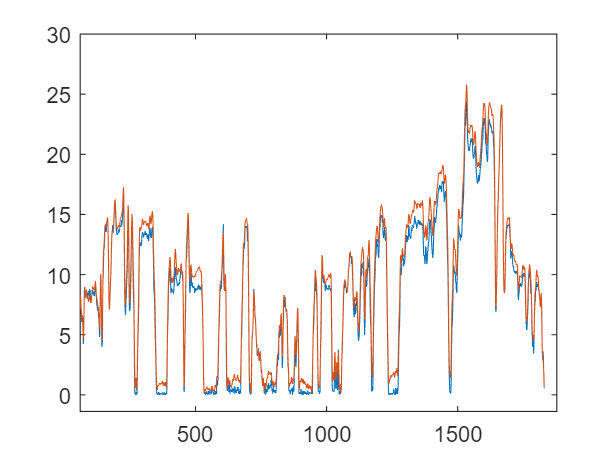

xdot1 = filtfilt(d2, xdot);

x = filtfilt(d1, gradeneu);
y = filtfilt(d1, grade1);








myCycle = [t,xdot];
myGrade = [t, grade1]; 